# Projecting functions

n_points = 21;

lo_bound = -pi;
hi_bound = pi;

dx = (hi_bound - lo_bound) / (n_points - 1); % n points, n-1 intervals

base = linspace(lo_bound, hi_bound, n_points)'; 
base

base =    -3.1416
   -2.8274
   -2.5133
   -2.1991
   -1.8850
   -1.5708
   -1.2566
   -0.9425
   -0.6283
   -0.3142


% set up input vectors; in this case 1, x, x^2, ..., x^5
n_deg = 6; % degrees 0 to 5. 6 different degrees.
V = zeros(n_points, n_deg, 'double');

for ii = 1:n_deg
    V(:, ii) = base .^ (ii-1);
end

V

V =     1.0000   -3.1416    9.8696  -31.0063   97.4091 -306.0197
    1.0000   -2.8274    7.9944  -22.6036   63.9101 -180.7016
    1.0000   -2.5133    6.3165  -15.8752   39.8988 -100.2765
    1.0000   -2.1991    4.8361  -10.6352   23.3879  -51.4327
    1.0000   -1.8850    3.5531   -6.6974   12.6242  -23.7961
    1.0000   -1.5708    2.4674   -3.8758    6.0881   -9.5631
    1.0000   -1.2566    1.5791   -1.9844    2.4937   -3.1336
    1.0000   -0.9425    0.8883   -0.8372    0.7890   -0.7436
    1.0000   -0.6283    0.3948   -0.2481    0.1559   -0.0979
    1.0000   -0.3142    0.0987   -0.0310    0.0097   -0.0031


## Gram-Schmidt to orthonormalize functions

W = gram_schmidt(V, dx);
W

W =     0.3893   -0.6430    0.7544   -0.7731    0.7228   -0.6269
    0.3893   -0.5787    0.5281   -0.3092    0.0000    0.3134
    0.3893   -0.5144    0.3256    0.0325   -0.3804    0.5609
    0.3893   -0.4501    0.1469    0.2658   -0.5073    0.4234
    0.3893   -0.3858   -0.0079    0.4042   -0.4588    0.1274
    0.3893   -0.3215   -0.1390    0.4611   -0.3029   -0.1719
    0.3893   -0.2572   -0.2462    0.4503   -0.0970   -0.3807
    0.3893   -0.1929   -0.3296    0.3852    0.1119   -0.4559
    0.3893   -0.1286   -0.3891    0.2794    0.2872   -0.3953
    0.3893   -0.0643   -0.4249    0.1465    0.4028   -0.2271


vec_to_approx = sin(base)

vec_to_approx =    -0.0000
   -0.3090
   -0.5878
   -0.8090
   -0.9511
   -1.0000
   -0.9511
   -0.8090
   -0.5878
   -0.3090


a = zeros(1, n_deg); % a is a row vector holding scaling values 

for ii = 1:n_deg
    a(:, ii) = func_inner_prod(vec_to_approx, W(:, ii), dx)...
        /func_inner_prod(W(:, ii), W(:, ii), dx);
end
    
a

a =    -0.0000    1.2753    0.0000   -1.2148   -0.0000    0.1980


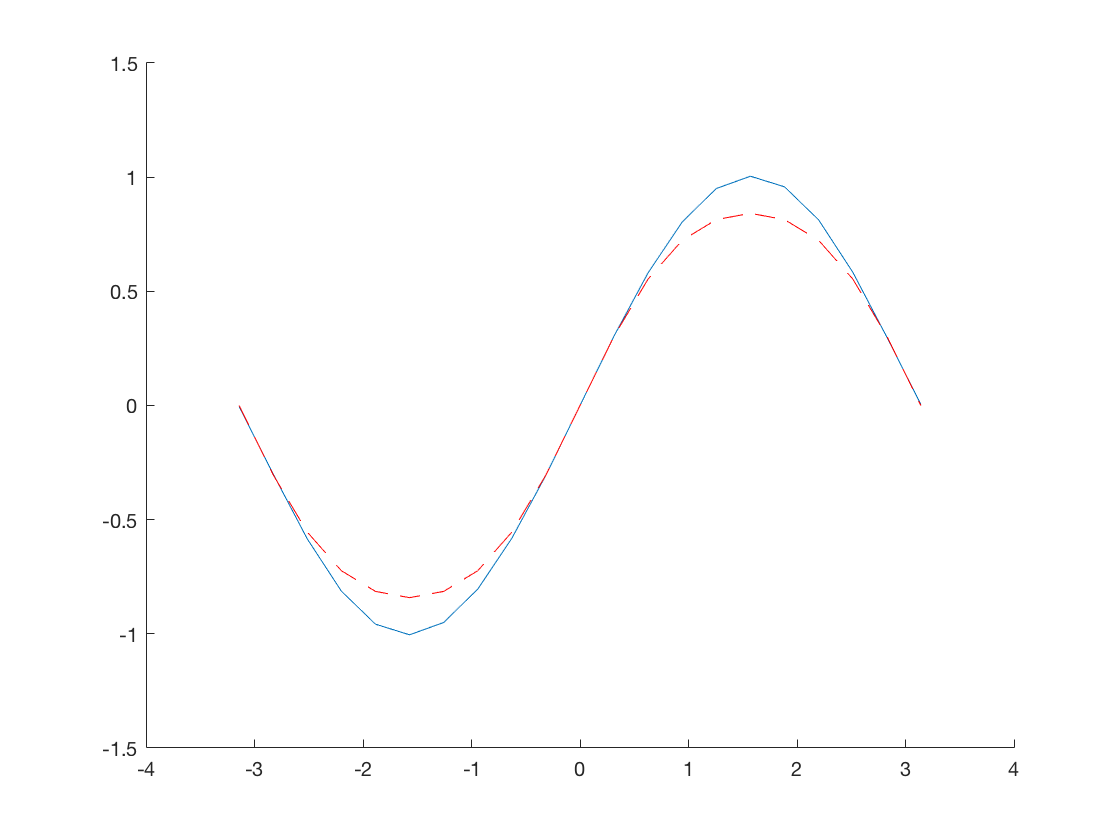

% This following code snippet verifies that gram schmidt works with
% functions - norm = 1 and inner project = 0 for different bases
%
% for ii = 1:n_deg
%     fprintf('Vector %d norm is\n', ii);
%     func_inner_prod(W(:, ii), W(:, ii), dx)
%     for jj = ii+1:n_deg
%         fprintf('>>> Inner product with %d\n', jj);
%         func_inner_prod(W(:, ii), W(:, jj), dx)
%     end
% end

reconstructed = sum(W .* a, 2); % sum across rows
taylor_approx = vec_to_approx - vec_to_approx .^ 3 / factorial(3)...
    + vec_to_approx .^ 5 / factorial(5);

figure;hold on
plot(base, reconstructed);
plot(base, taylor_approx, 'r--')